clear
asset_path = "../docs/assets/";
A = imread([asset_path + "parrot.png"]);
if size(A, 3) == 3
    A = rgb2gray(A);
end
A = im2double(A);

% Compute SVD
[U, S, V] = svd(A);

% Keep top k singular values
k = 50:50:500;
A_ks = zeros([length(k) size(A)])

A_ks = A_ks(:,:,1) =

     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0

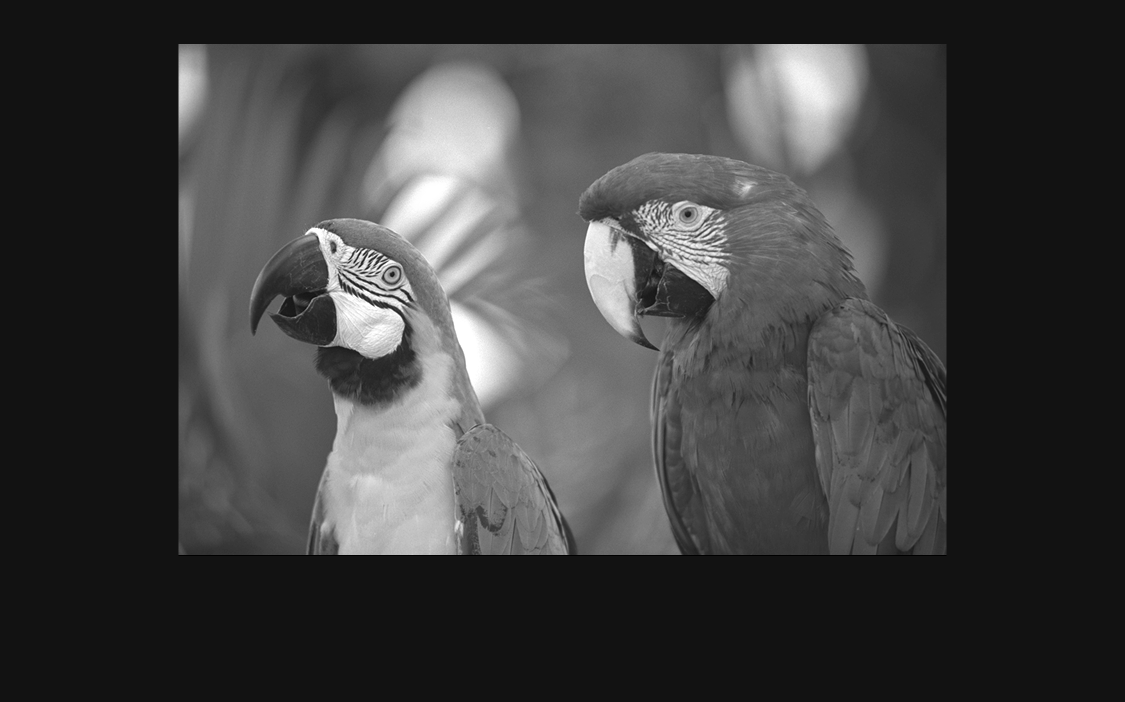

for i = 1:length(k)
    A_ks(i, :, :) = U(:, 1:k(i)) * S(1:k(i), 1:k(i)) * V(:, 1:k(i))';
    figure;
    imshow(squeeze(A_ks(i, :, :)));
    %title(["Rank " + num2str(k(i)) + " approximation"]);
    saveas(gcf, [asset_path + "svd-" + num2str(k(i)) + ".png"]);
    close(gcf);
end

figure;
imshow(A);
saveas(gcf, [asset_path + "grey-parrot.png"]);